## Customized canopy and terrain height calculation

Version 5 of the ATL08 product provides measurements of canopy and terrain heights in predetermined 20 m and 100 m segments. However, with the xATLy toolbox, you can go beyond these fixed segment lengths and customize your own preferred segment lengths while also controlling the number of data points to use in your calculations. 

This notebook will guide you through the process of utilizing the toolbox to compute canopy and terrain heights in custom segment lengths.

- Creating Atl03, Atl08 and ground track objects

- Steps for customized calculation of  canopy and terrain heights

- Saving calculated canopy and terrain heights

- Generating custom segment polygons

- Concluding remarks

### Create Atl03, Atl08 and ground track objects

For this activity, you will be working with an ATL03/ATL08 granule obtained in 2019 from a region in northwestern Zambia. However, you may choose to use a different granule, but be sure to modify the file paths accordingly.

Create `Atl03` and `Atl08` objects using file paths provided below. 

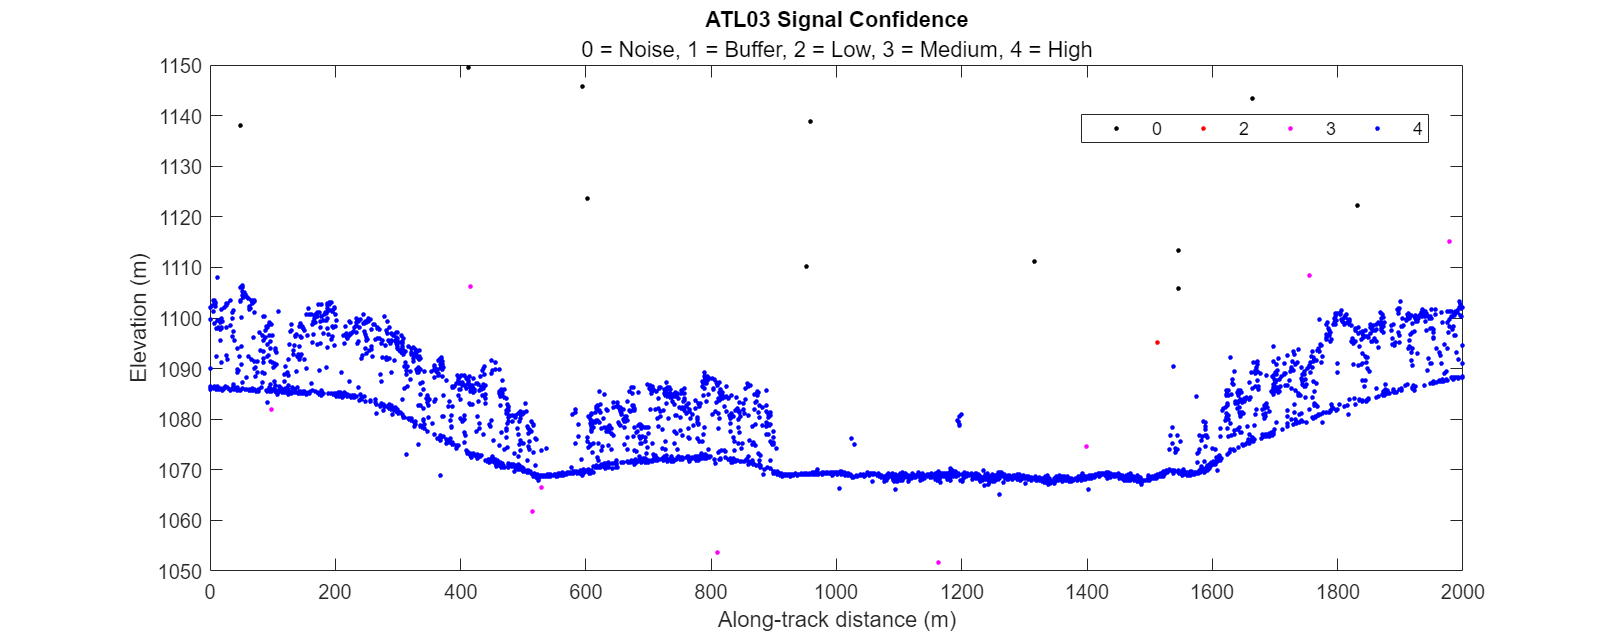

atl03path = "./data/ATL03_20190603025340_10050314_002_01.h5"; % ATL03 filepath
atl08path = "./data/ATL08_20190603025340_10050314_002_01.h5"; % ATL08 filepath

% create an Atl03 and Atl08 objects
a3 = Atl03(atl03path);
a8 = Atl08(atl08path);

% create ground track object. Here we select the srtong beeam from middle
% ground track pair, gt2l. To see available you may use a3.gettracklist() 
% or a8.gettracklist();% The track you choose must be available in Atl03 
% and Atl08 objects

gt = gtrack('gt1l',a3,a8);

% visualize section of the data
atdlim = [0,2000];

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.6]);

% plot raw point cloud with signal confidence rendering 
atdplot(gt,'s',[],atdlim) % group points by signal confidence, use default colors
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

### Calculate canopy and terrain heights

The process of calculating canopy and terrain heights typically involves multiple steps, such as obtaining a classified point cloud, fitting the ground level, normalizing the aboveground height, and computing the canopy and terrain metrics. While the `getnormalizedpc `method can handle the first three steps with a single function call, a more detailed and informative approach is provided below, where each step is broken down and explained, allowing for a better understanding of the parameters being used.

#### *1. Retrieve classified point cloud using *`getclassedpc`* method.*

 The `getclassedpc` method serves the purpose of retrieving a classified point cloud by merging the ATL08 photon classes (classed_pc_flag) with the raw ATL03 point cloud. Along with the `Atl03` and `Atl08` objects, the method takes two optional parameters:

- inc_these_seg_attrib: This parameter allows for the inclusion of ATL08 segment-level attributes in the point cloud.

- clip_aoi: Enabling this parameter results in the returned point cloud being clipped to a specific area of interest.

In this demonstration, we will include the msw_flag and night_flag to provide further information on atmospheric scattering and night/day acquisition. 

inc_these_seg_attrib = {'msw_flag','night_flag'};
pc = getclassedpc(gt,inc_these_seg_attrib);% No clipping to area of interest

% display table columns
disp(string(pc.Properties.VariableNames)')

    "segment_id"
    "photon_index"
    "alongtrack_distance"
    "deltatime"
    "longitude"
    "latitude"
    "elevation"
    "signal_conf"
    "classed_pc_flag"
    "segment_id_beg"
    "msw_flag"
    "night_flag"



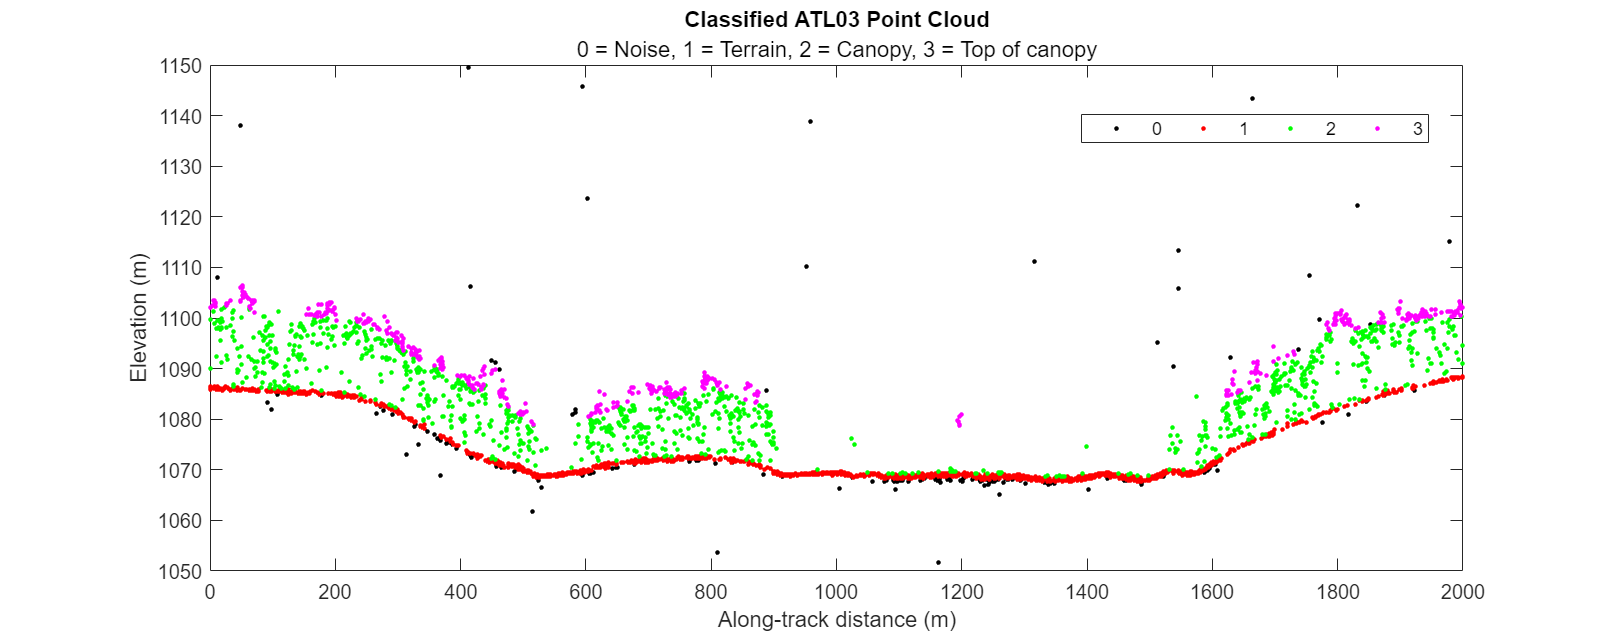


% visualize section of the data
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.6]);

% plot classified point cloud 
plothis = 'c'; % photn class
colors = 'krgm'; % black for noise,red = terrain etc
excludenoisepts = false; % includes noise points

atdplot(gt,plothis, colors, atdlim, excludenoisepts) 
box on
xlim([atdlim(1),atdlim(2)])
ylim([1050,1150])

#### *2. Fit ground level using the *`fitgroundmodel`* function. *

Since ICESat-2 measures along tracks, the xATLy toolbox models terrain surfaces as one-dimensional curves, following these steps:

- Terrain points are extracted from the classified point cloud and used to create curves, with along-track distance and elevation serving as x- and y-axis values, respectively.

- In order to generate smoother curves through the points, the terrain points are binned at fixed interval distances.

- The representative elevation value for each bin is calculated as the median elevation value.

- A curve is interpolated to connect all the bin elevations, utilizing a specified interpolation method.

In the xATLy toolbox, the `fitgroundmodel` function is utilized to fit a curve to the terrain points, resulting in both a curve fit object or function (grndFunc), as well as the ground points (gpts) utilized during the fitting process, as shown below.

% fit ground level
grndInterval = 10; % binning distance
interpolatemethod = 'smoothingspline';%'other options 'linearinterp','cubicspline';
robustfit = false; % no robust fitting using RANSAC. This is still experimnetal
[grndFunc, gpts] = fitgroundmodel(pc,grndInterval,interpolatemethod,robustfit);

The following lines of code plot the point cloud together with the fitted ground curve. We use tiled layout to show zoomed views of two sections of the data to clearly show details on the binning and fitting.

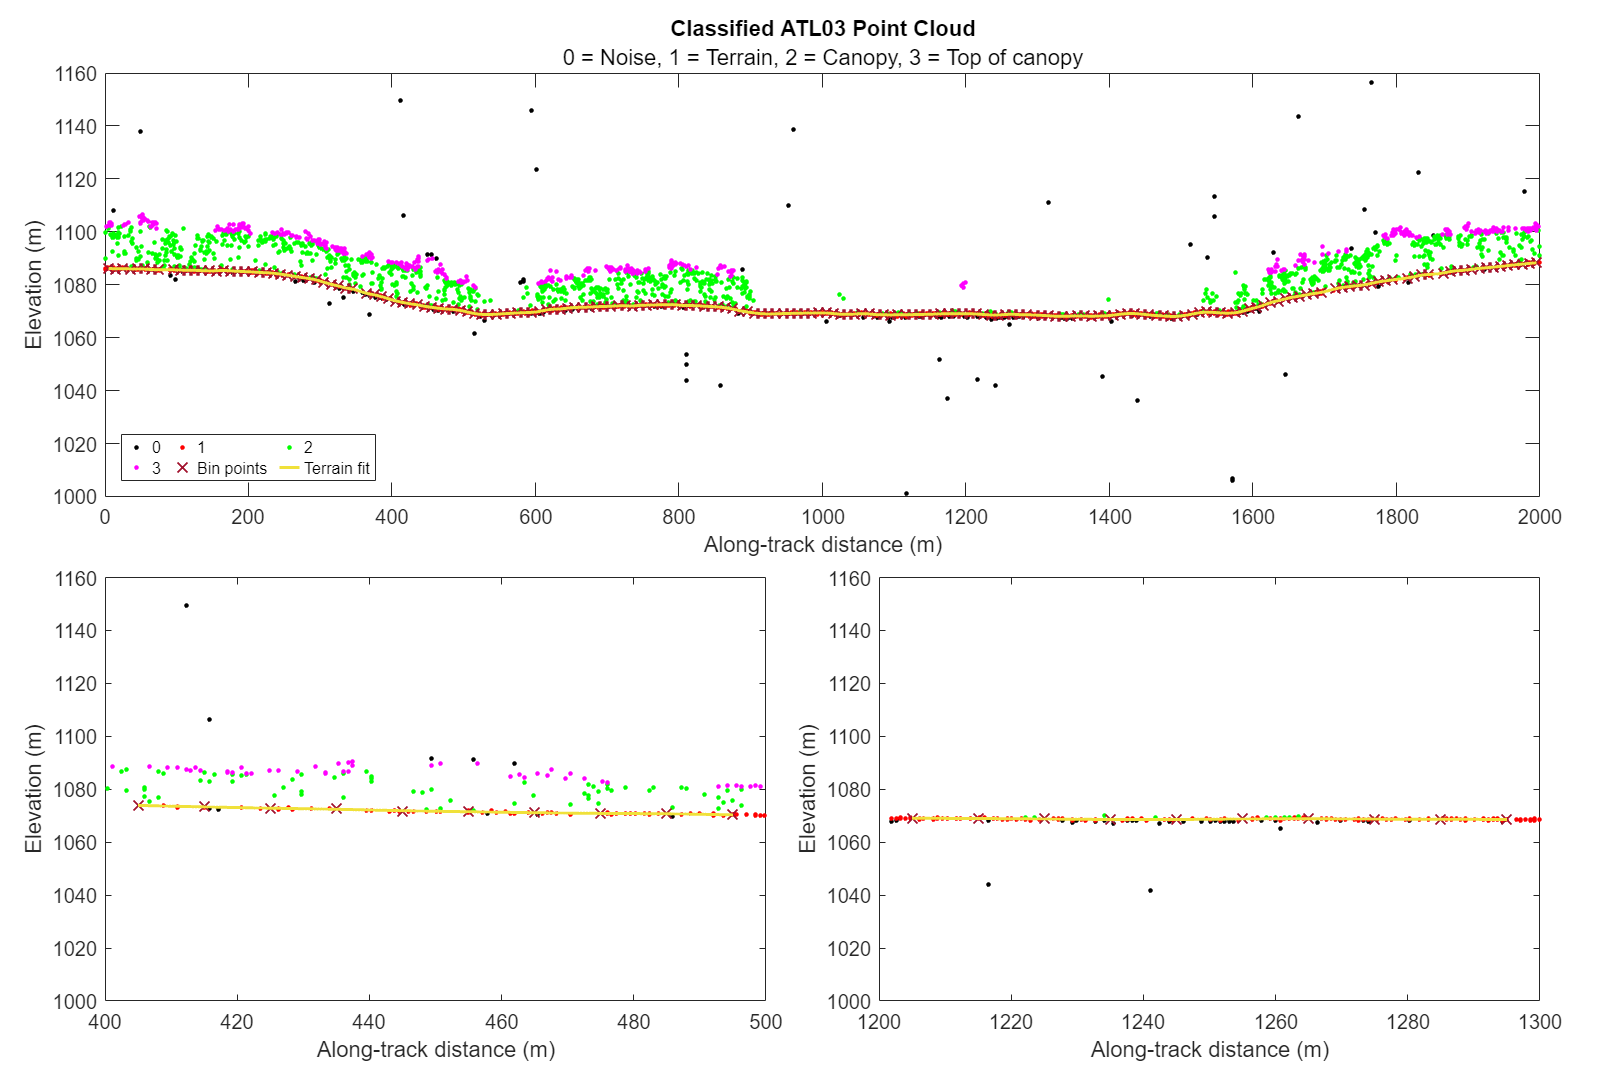

% Visualize fitted ground surface
figure('units','normalized','outerposition',[0.0 0.0 0.85 1]);
t = tiledlayout(2,2);

nexttile(1,[1,2])
atdlim = [0,2000];
mksize =  7;
plothis = 'c';
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.DisplayName = 'Bin points';
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.DisplayName = 'Terrain fit';
cg.Color = [ 0.9412,0.8824,0.2275];
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
lg2 = legend('Orientation','horizontal','Location','southwest','NumColumns',3,'FontSize',8);
lg2.ItemTokenSize(1) = 10;
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off

nexttile
atdlim = [400,500];
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.Color = [ 0.9412,0.8824,0.2275];
lg2 = legend('off');

title('')
subtitle('')
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off

nexttile
atdlim = [1200,1300];
atdplot(pc,plothis, colors, atdlim, excludenoisepts); 

hold on
cf = and(gpts(:,1) >= atdlim(1),gpts(:,1) <=atdlim(2));
hh = plot(grndFunc,gpts(cf,1),gpts(cf,2)); %

set(hh,'MarkerSize',mksize, 'LineWidth',1.5);
dg = hh(1);
dg.Color = [0.6353 0.0784 0.1843];
dg.MarkerSize = mksize;
dg.Marker = 'x';
dg.LineWidth = 1;

cg = hh(2);
cg.Color = [ 0.9412,0.8824,0.2275];
lg2 = legend('off');
xlabel('Along-track distance (m)')
ylabel('Elevation (m)')
title('')
subtitle('')
xlim([atdlim(1),atdlim(2)])
ylim([1000,1160])
hold off
t.TileSpacing = 'compact';
t.Padding = 'compact';

#### 3. Normalize point cloud using `normalizepts` function

Using the `normalizepts` function, the fitted ground curve model is employed to estimate the ground level at each point. This estimated ground level is then subtracted from the point elevation, resulting in the aboveground level heights. Any points below the fitted ground curve will have negative aboveground heights. The *removeptsbelow* parameter provides the option to either remove or retain these points with negative heights, as demonstrated below.

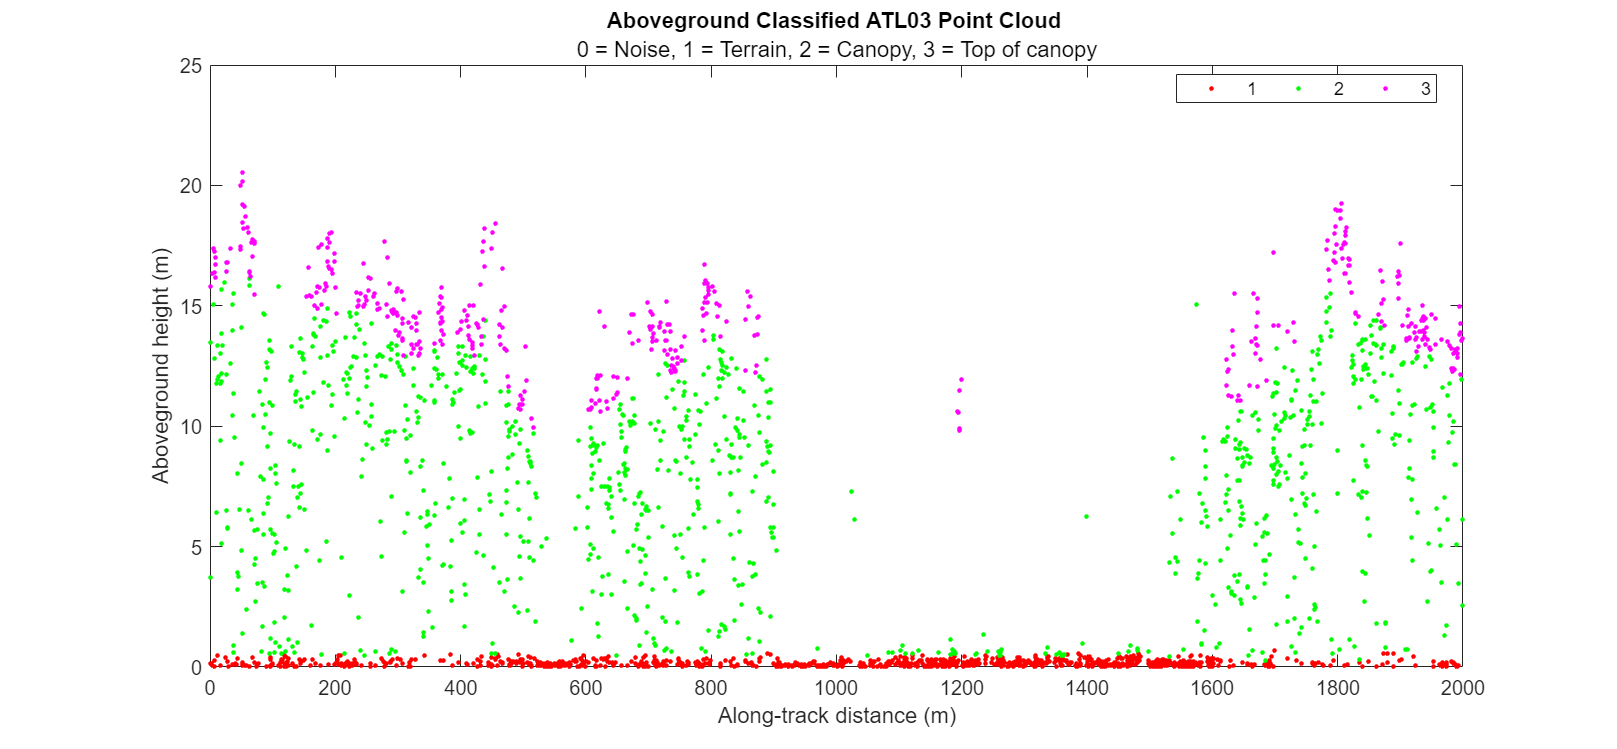

removeptsbelow = true; % gets rid of any point below fitted ground level
npc = normalizepts(pc,grndFunc, removeptsbelow);

% Visualize output
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.0 0.0 0.85 0.6]);

% plot classified point cloud 
plothis = 'n'; % photn class
colors = 'rgm'; % black for noise,red = terrain etc
excludenoisepts = true; % includes noise points

atdplot(gt,plothis, colors, atdlim, excludenoisepts) 
box on
xlim([atdlim(1),atdlim(2)])
ylim([0,25])

#### 4. Calculate canopy and terrain height using the h`metrics` function

With the `hmetrics` function, canopy and terrain metrics are computed for each segment utilizing normalized point cloud data. The function allows for the specification of a segment length as well as a minimum number of points required for a valid calculation. Additionally, multiple canopy height percentiles can be included, and the minimum allowable canopy height can be controlled as desired.

% calculation parameters
segLength = 30; % use 30 m segment length
canopy_percentiles = [50,98]; % calculate 50th and 98th canopy height percentiles
minpts = 9; % set min number of points for valid calculation
min_h = 2; % set min canopy height returned
includeground = true; % includes ground points in canopy height percentile calculation

% calculate canopy and terrain heights
cH = hmetrics(npc, segLength,canopy_percentiles,minpts,min_h, includeground);

% display first 5 rows, limt columns for space to:
% 1:4 -> seg_id, seg_atd, seg_lon, seg_lat
% 9:11 - > seg_npts, seg_ca_pts, seg_te_pts
% 17 -> h_ca_p98 (98th percentile canopy height)
disp(cH(1:5,[1:4,9:11,17])) 

    seg_id    seg_atd    seg_lon    seg_lat    seg_npts    seg_ca_pts    seg_te_pts    h_ca_p98
    ______    _______    _______    _______    ________    __________    __________    ________

     1.00      15.00      23.80     -13.72      44.00        34.00         10.00        17.36  
     2.00      45.00      23.80     -13.72      41.00        31.00         10.00        20.53  
     3.00      75.00      23.80     -13.71      41.00        36.00          5.00        17.99  
     4.00     105.00      23.80     -13.71      49.00        31.00         18.00        15.80  
     5.00     135.00      23.80     -13.71      49.00        33.00         16.00        13.61  



The `hmetrics` function outputs various attributes by default, including the central segment coordinates (seg_lat/seg_lon), as well as the coordinates marking the beginning (seg_lat_beg/seg_lon_beg) and end (seg_lat_end/seg_lon_end) of the segment. The resulting table also includes information on the number of points within the segment (seg_npts), which is further broken down into terrain (seg_te_pts) and off-terrain canopy (seg_ca_pts). Additionally, the function calculates default metrics such as the minimum, mean, maximum, and standard deviation for both canopy and terrain heights.

The figure below shows normalized point cloud data overlain with the calculated 98th percentile canopy height.

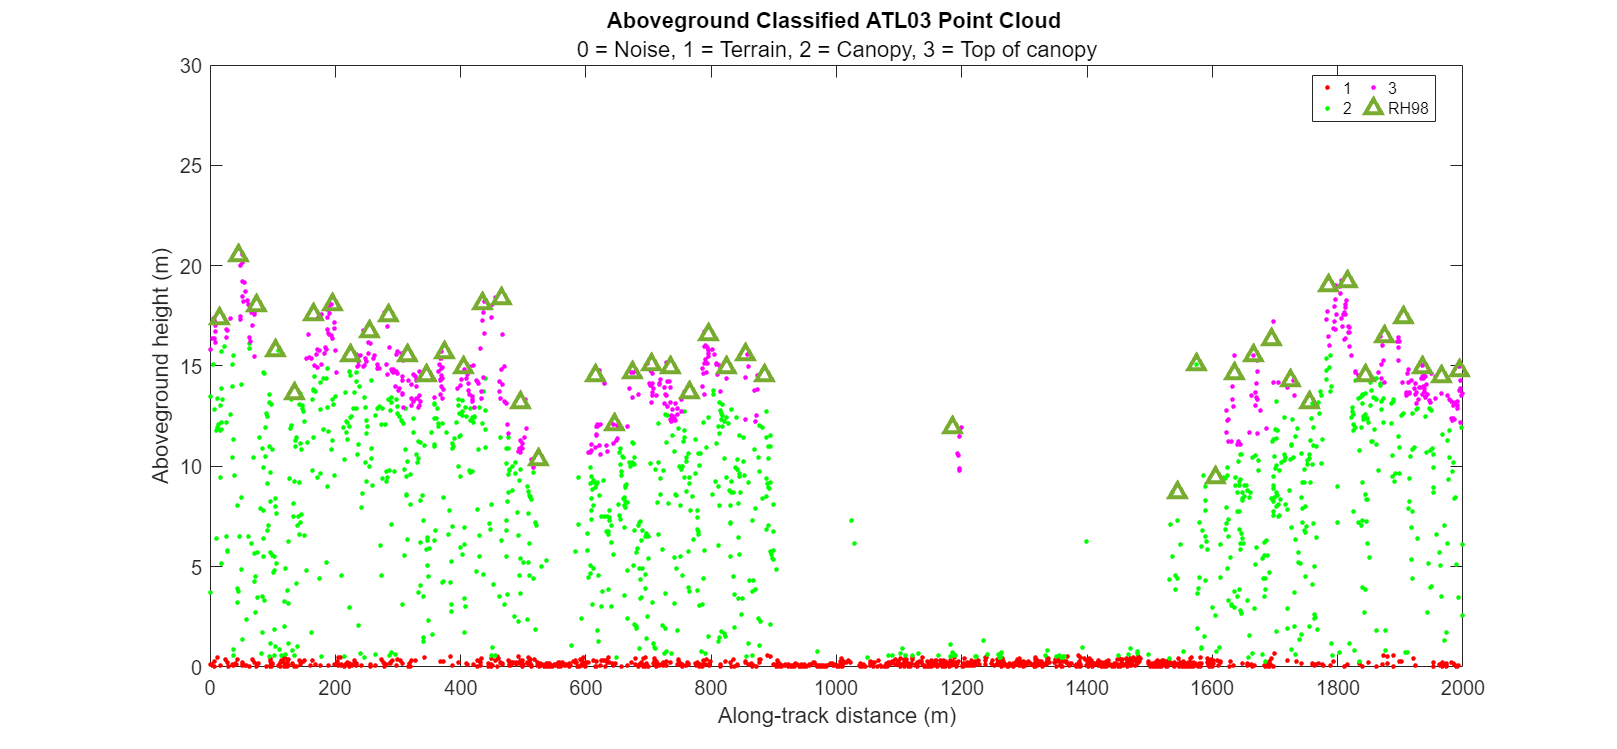

% visualize output
atdlim = [0,2000];
mksize =  3;

figure('units','normalized','outerposition',[0.2 0.0 0.85 0.6]);

% plot classified point cloud 
plothis = 'n'; % photn class
colors = 'rgm'; % black for noise,red = terrain etc
excludenoisepts = true; % includes noise points
% normalized point cloud
atdplot(npc,plothis, colors, atdlim, excludenoisepts) 
box on

% overlay with calculated 98th percentile height
hold on
clr = [0.4667 0.6745 0.1882];
ch = 'RH98'; % 98th percentile height;
tf2 = and(cH.seg_atd >= atdlim(1), cH.seg_atd <= atdlim(2));
plot(cH.seg_atd(tf2),cH.h_ca_p98(tf2),'^','Color',clr,...
                'MarkerSize',7,'LineWidth',2,'DisplayName',ch)
hold off

lg3 = legend('Orientation','vertical','Location','best','NumColumns',2,'FontSize',8);
lg3.ItemTokenSize(1) = 10;
xlim([atdlim(1),atdlim(2)])
ylim([0,30])

#### Combining steps 1 -3

In case you are only interested in calculating heights, steps 1 - 3 can be combined as follows:

% parameters
inc_these_seg_attrib = {'msw_flag','night_flag'};
clip_aoi = []; % no clipping enabled
grndInterval = 10;
interpolatemethod = 'smoothingspline';
robustfit = false;
removeptsbelow = true;

% get normalized points directly
npc = gt.getnormalizedpc(inc_these_seg_attrib, clip_aoi, grndInterval,...
                interpolatemethod,robustfit, removeptsbelow);

% calculation parameters
segLength = 30; % use 30 m segment length
pcTile = [50,98]; % calculate 50th and 98th canopy height percentiles
minPts = 9; % set min number of points for valid calculation
minCH = 2; % set min canopy height returned
includeground = true; % includes ground points in canopy height percentile calculation



% calculate canopy and terrain heights
cH = hmetrics(npc, segLength,pcTile,minPts,minCH, includeground);
disp(cH(1:5,[1:4,9:11,17])) % display first 10 rows, limit columns

    seg_id    seg_atd    seg_lon    seg_lat    seg_npts    seg_ca_pts    seg_te_pts    h_ca_p98
    ______    _______    _______    _______    ________    __________    __________    ________

      1          15      23.802     -13.715       44           34            10         17.359 
      2          45      23.802     -13.715       41           31            10         20.531 
      3          75      23.802     -13.715       41           36             5         17.994 
      4         105      23.802     -13.715       49           31            18         15.796 
      5         135      23.802     -13.714       49           33            16         13.609 



### Saving calculated canopy and terrain heights

Similar to all derived attribute data, calculated canopy and terrain height metrics can readily be saved as ASCII text files to facilitate further analyses. The code below saves the *cH* table retrieved in the preceding steps to a CSV file using the `savetable` function

pc_fn = './temp/gt1l_tbl_ch.csv';
savetable(cH,pc_fn) % writes the classified pc

### Generate custom segment polygons

Similar to ATL08 data, the xATLy toolbox allows for the creation of segment polygons based on the custom canopy height data. These polygons can be used for various tasks, including validation or metric comparison, as well as visualization purposes. To generate these segment polygons, the toolbox utilizes the beginning and end coordinates of each segment in addition to a set segment width that approximates the lidar footprint.

segmentwidth = 11; % sets output segment width to 11 m
outshp = '.\temp\customseg.shp'; % output shapefile, WGS84 geo
clip_aoi = []; % no clipping to area of interest
writecustomsegpol(cH, outshp, segmentwidth, clip_aoi)

### Concluding remarks

This notebook showcased the use of the xATLy toolbox for generating custom canopy and terrain heights using ATL03 and ATL08 data. However, it's important to note that the current version of the toolbox utilizes the ATL08 photon classification data without any refinement. As a result, any errors in the ATL08 product's classification may impact the accuracy of the derived canopy and terrain heights.

For additional processing options, please refer to the class methods or function definitions provided in the xATLy toolbox.